# 案例：Matlab 基础绘图，附上 6 种超好看的淡色

clear;clc;
x = 0:0.4:2*pi;
y1 = sin(x);
y2 = cos(x);
y3 = 0.2*x;
y4 = 0.05*x.^2;
y5 = 1./(1+x);
y6 = y1 + y2;

% 在一个 figure 中绘制多个子图，(2, 1, 1) 表示 2 行 1 列第 1 个子图
subplot(2, 1, 1)   
plot(x, y1, '-d', 'Color', 'r', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'y', 'MarkerSize', 10)
% d：表示倒置的菱形，-d表示用实线连接，r表示曲线红色，
% MarkerEdgeColor表示标记点轮廓颜色，MarkerFaceColor 表示标记点内部颜色，MarkerSize表示标记大小
% 各种线型、符号、颜色代码参考帮助，如下

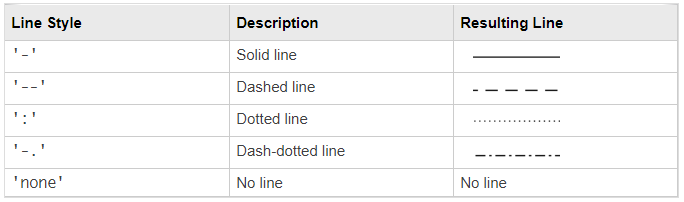

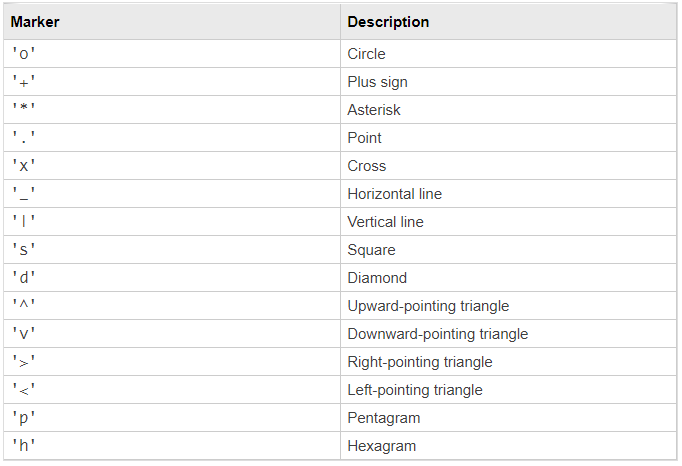

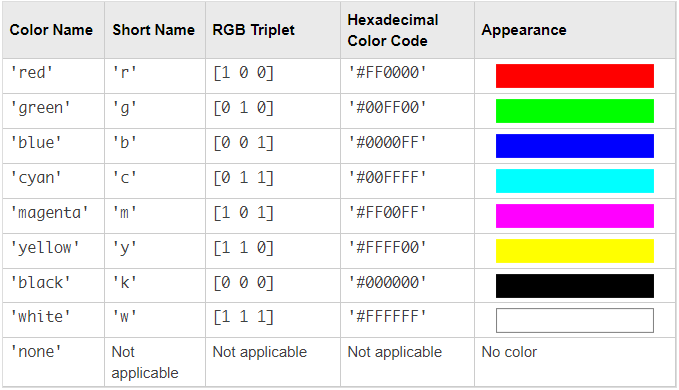

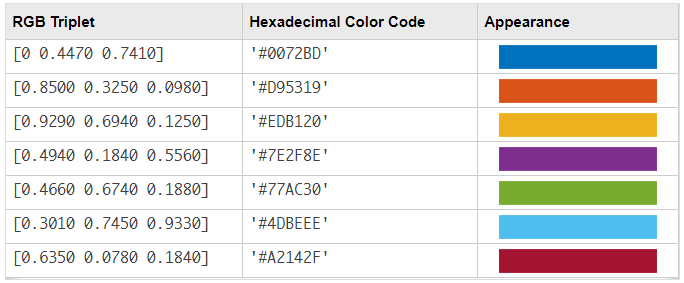

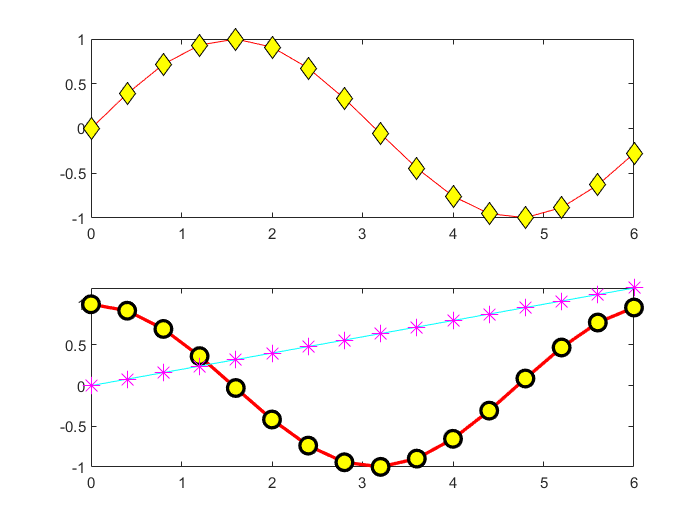

% 一张图绘制多条曲线
subplot(2, 1, 2)
plot(x, y2, '-o', 'LineWidth', 2, 'Color', 'r', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'y', 'MarkerSize', 10)
hold on 
plot(x, y3, '-*', 'Color', 'c', 'MarkerEdgeColor', [1 0 1], 'MarkerFaceColor', 'green', 'MarkerSize', 10)
hold off 

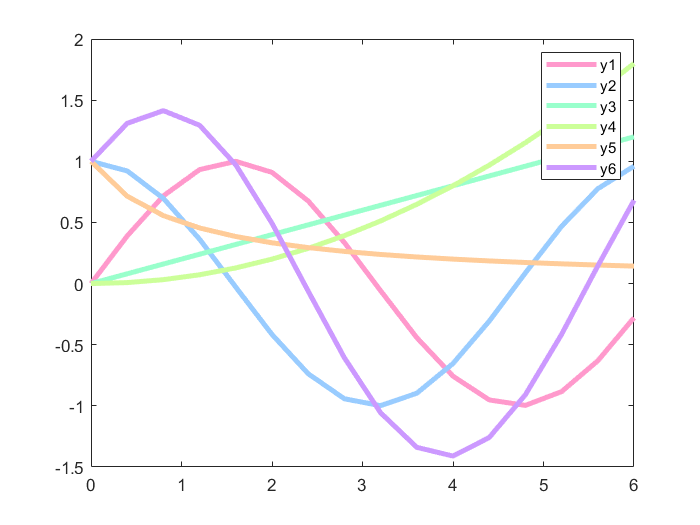


% 新建一张图 
% 演示 6 种超好看的淡色系效果图
figure;
plot(x, y1, 'Color', [1, 0.6, 0.8], 'LineWidth', 3);
hold on
plot(x, y2, 'Color', [0.6, 0.8, 1], 'LineWidth', 3);
plot(x, y3, 'Color', [0.6, 1, 0.8], 'LineWidth', 3);
plot(x, y4, 'Color', [0.8, 1, 0.6], 'LineWidth', 3);
plot(x, y5, 'Color', [1, 0.8, 0.6], 'LineWidth', 3);
plot(x, y6, 'Color', [0.8, 0.6, 1], 'LineWidth', 3);
hold off
% 添加图例
% legend('y1', 'y2', 'y3', 'y4', 'y5', 'y6');
% 亦可
names = {'y1', 'y2', 'y3', 'y4', 'y5', 'y6'};
legend(names);